clear all; close all; clc;

Problem 1

- A

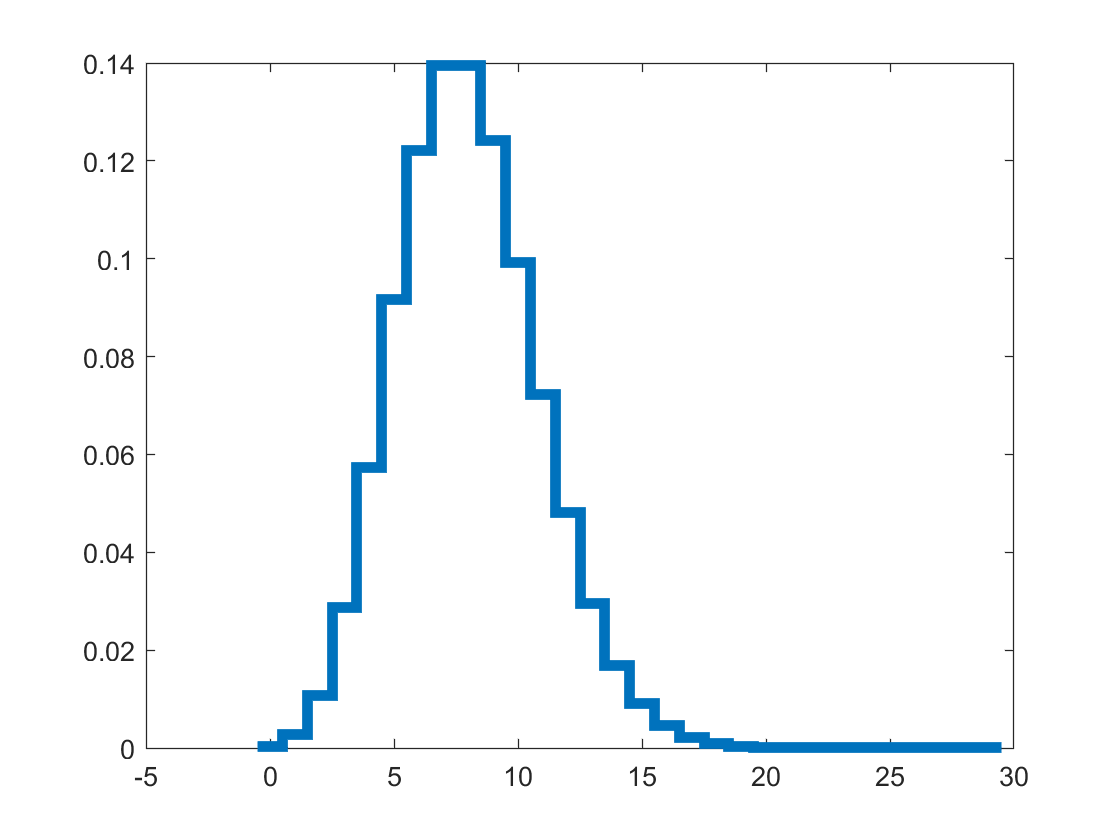

x = 0:30;
background = 8;
gammaRays = 10;
poisson = makedist("Poisson","lambda", background);
poissonPdf = pdf(poisson,x);
stairs(x-0.5, poissonPdf,"Linewidth", 4)

- B 

for three days

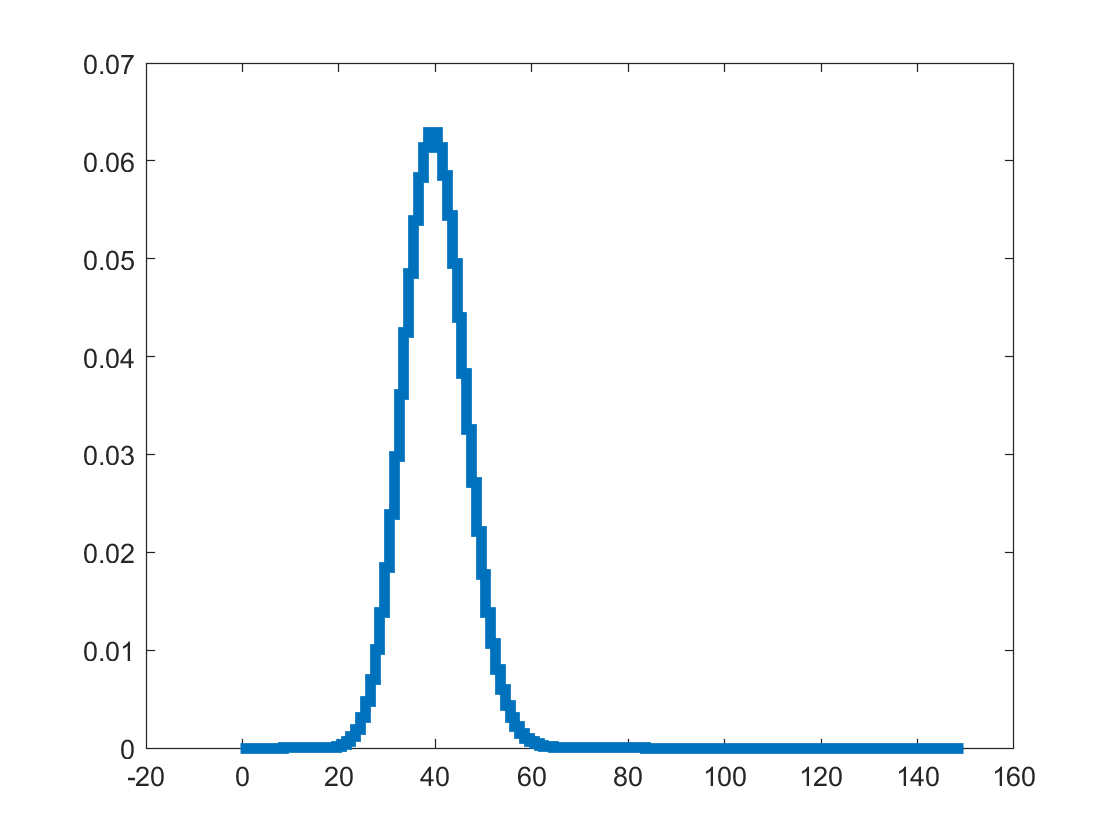

A = conv(poissonPdf,poissonPdf);
for i = 1:3
    A=conv(A,poissonPdf);
end
stairs((0:length(A)-1)-.5,A,"Linewidth", 4)

   1.C 

for twenty days

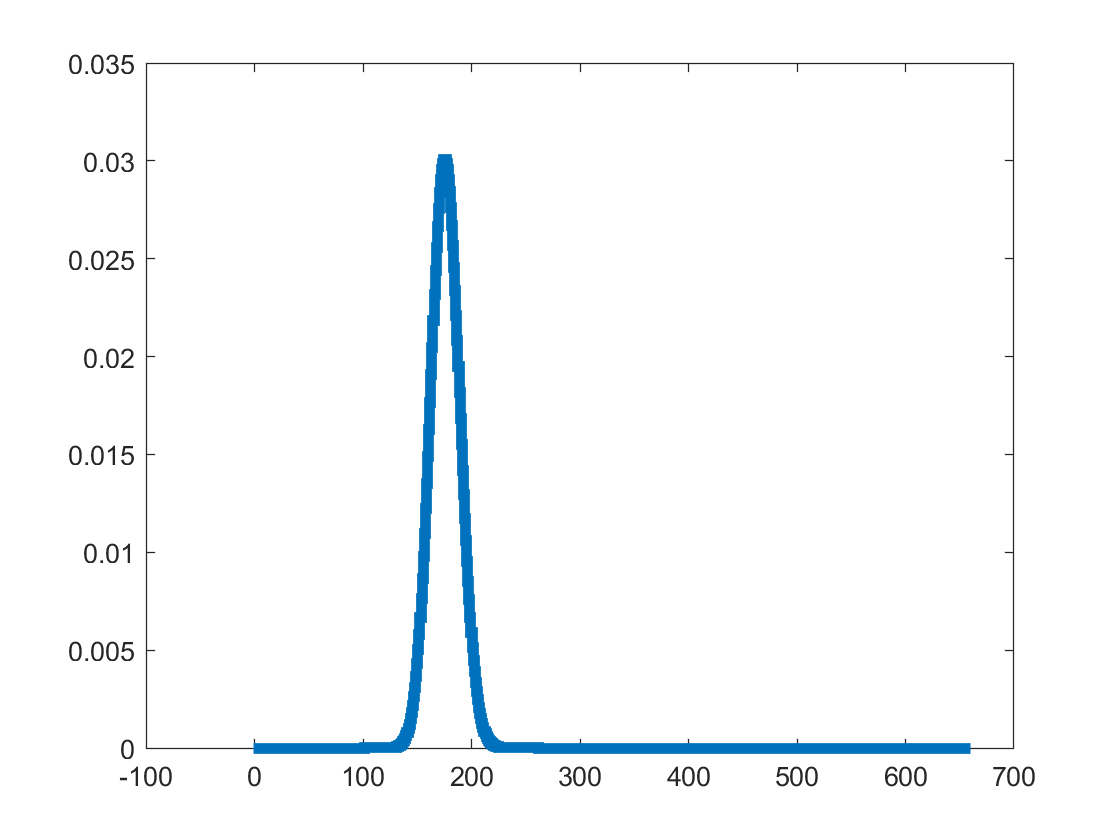

A = conv(poissonPdf,poissonPdf);
for i = 1:20
    A=conv(A,poissonPdf);
end
stairs((0:length(A)-1)-.5,A,"Linewidth", 4) 

for 50 days

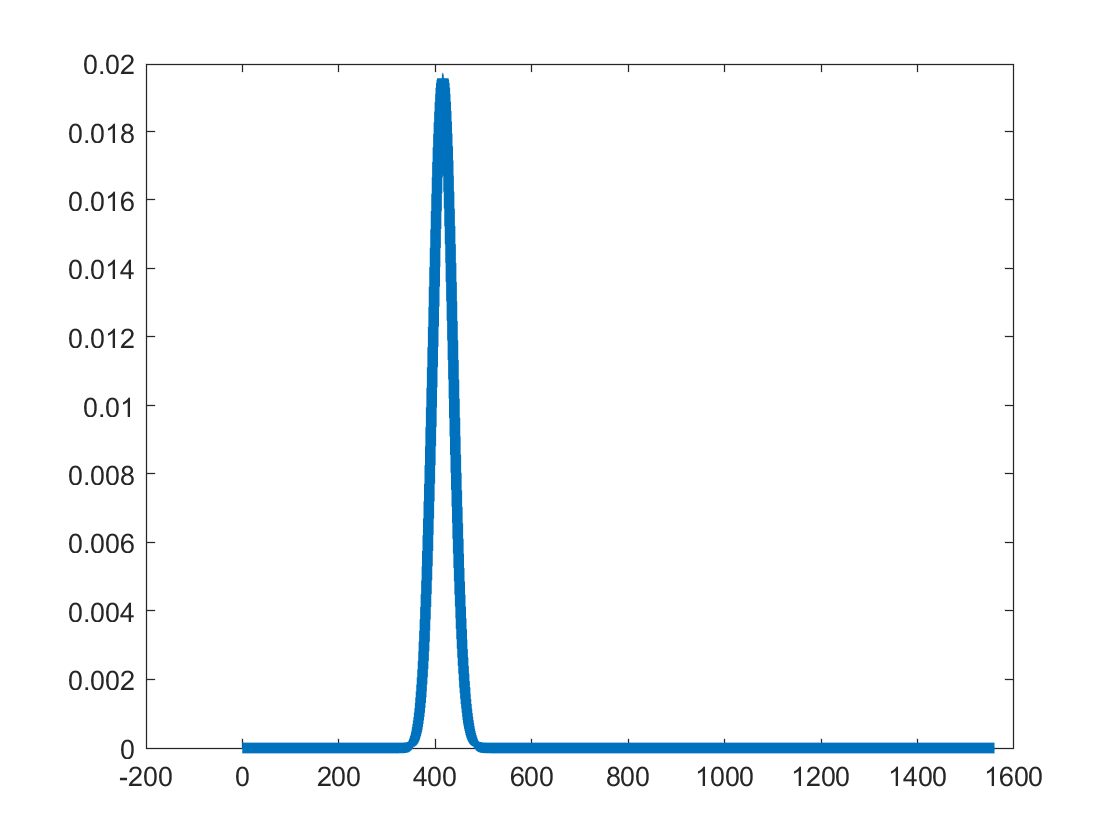

A = conv(poissonPdf,poissonPdf);
for i = 1:50
    A=conv(A,poissonPdf);
end
stairs((0:length(A)-1)-.5,A,"Linewidth", 4) 

for 100 days

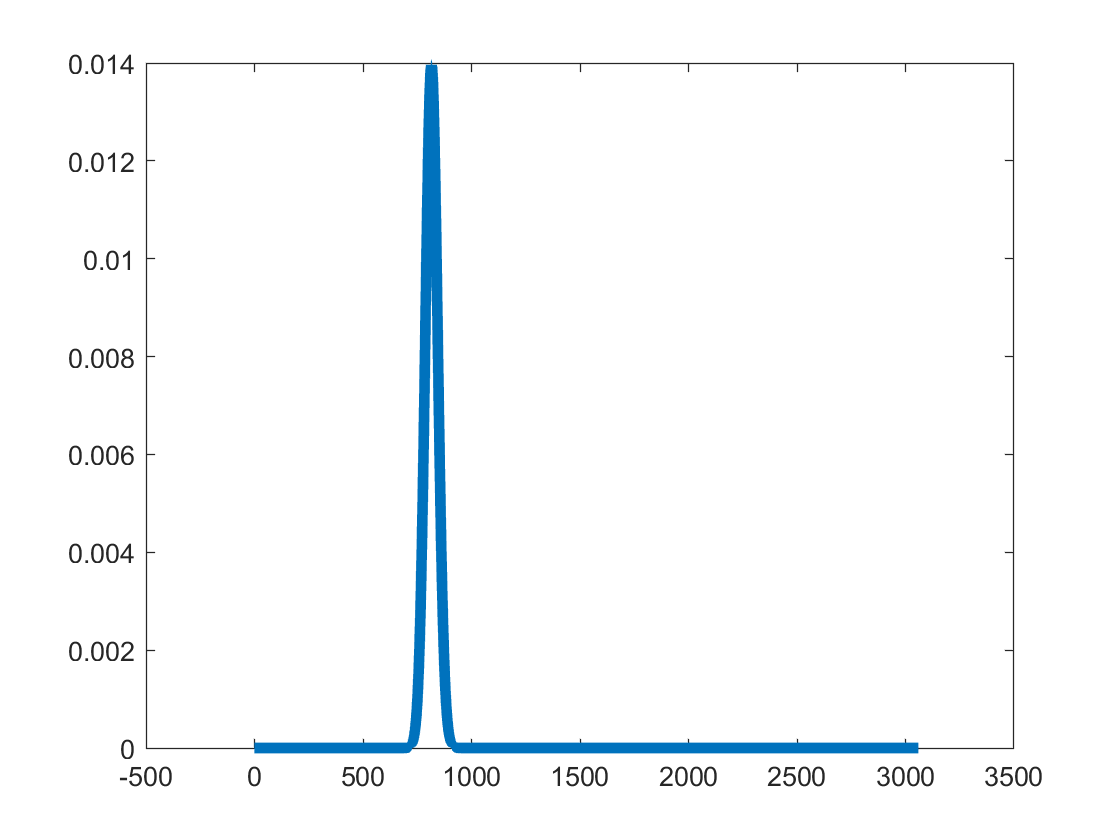

A = conv(poissonPdf,poissonPdf);
for i = 1:100
    A=conv(A,poissonPdf);
end
stairs((0:length(A)-1)-.5,A,"Linewidth", 4) 

- D 

On 4th day, I saw 10*4 gamma rays.

probability = 1-cdf(poisson, 40, "upper")

probability = 1.0000

sigmavalue = norminv(probability)

sigmavalue = 8.2095

That's a large sigma!

Problem 2

Chi-squared distribution

       2.A

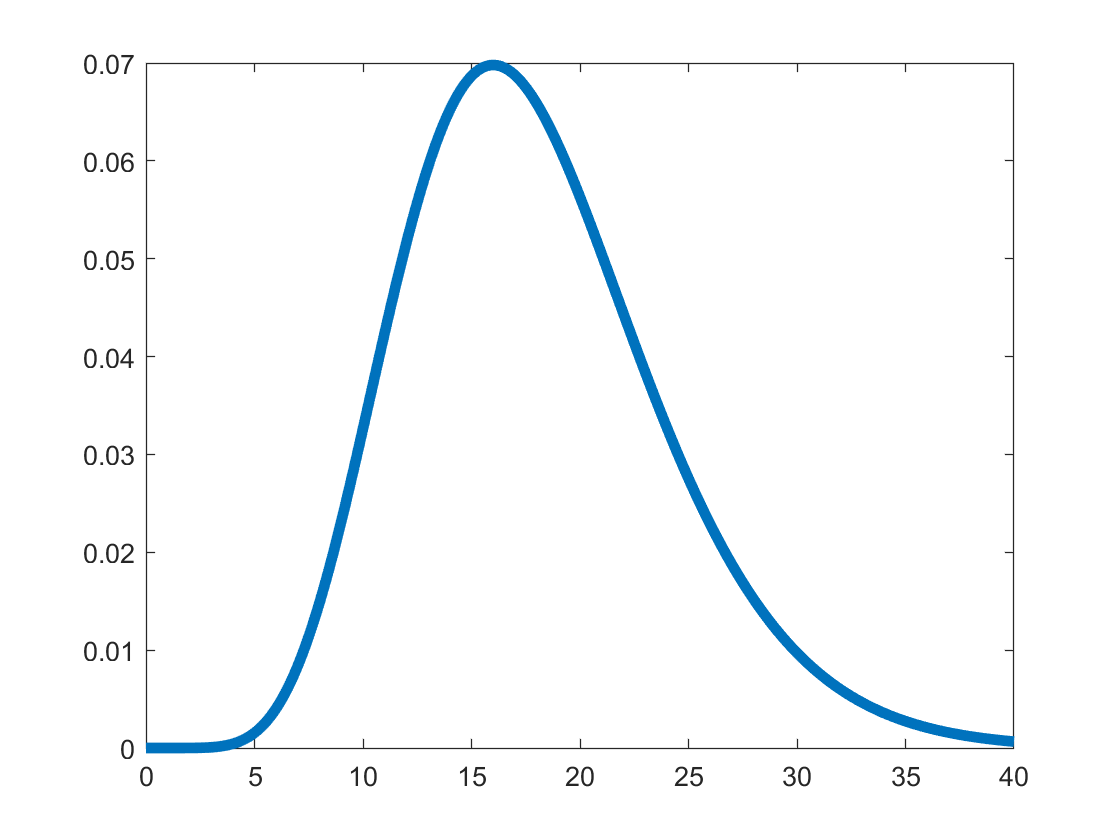

x = linspace(0,40,1000);
chisq = makedist("Gamma", 'a', 9,'b',2);
chisqPdf = pdf(chisq, x);
plot(x,chisqPdf,"Linewidth",4)

     2. B

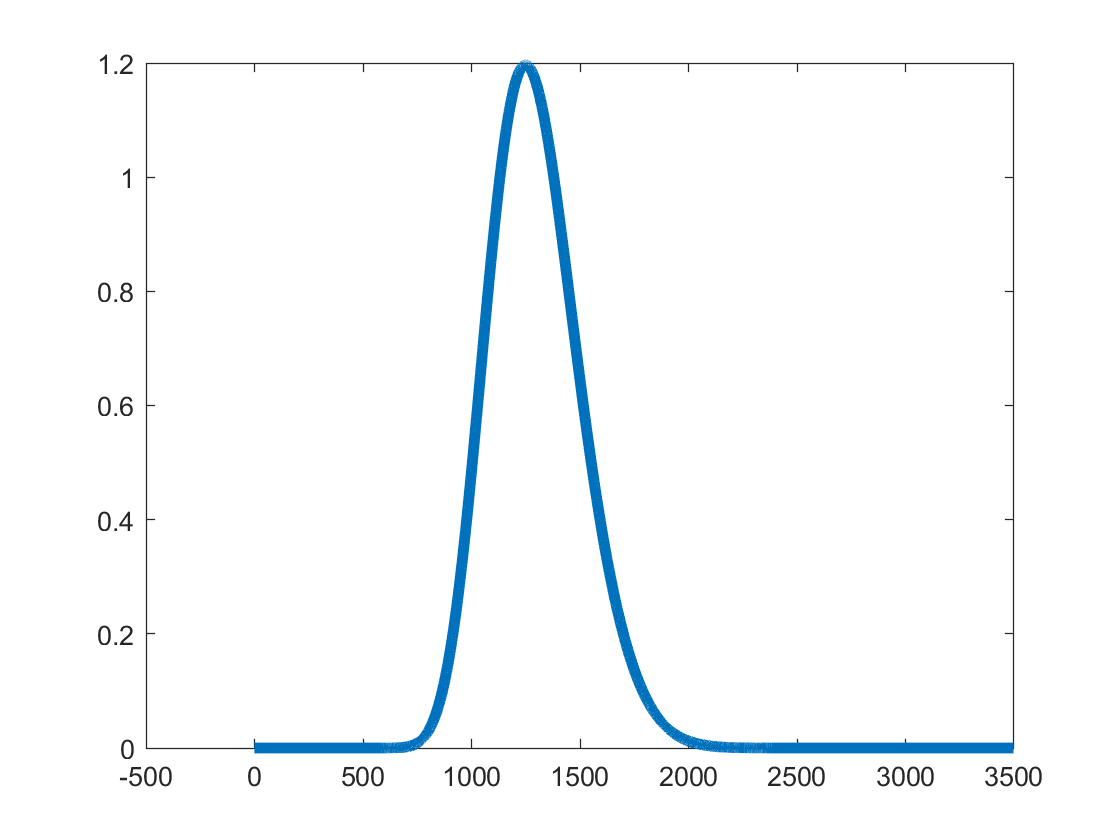

B = conv(chisqPdf,chisqPdf);
for i = 1:50
    B=conv(B,poissonPdf);
end
plot((0:length(B)-1)-.5,B,"Linewidth", 4) 

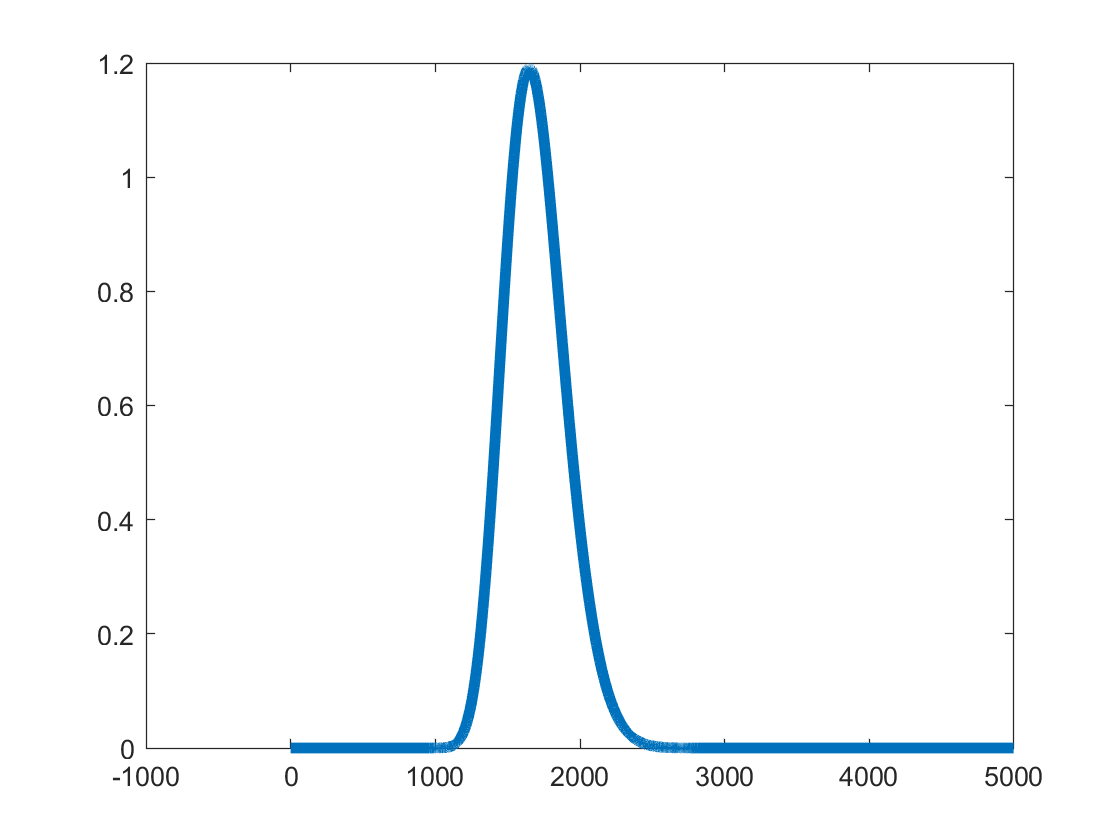


B = conv(chisqPdf,chisqPdf);
for i = 1:100
    B=conv(B,poissonPdf);
end
plot((0:length(B)-1)-.5,B,"Linewidth", 4) 

I would say after about 100 convolutions the function looks more or less Gaussian. After 50 convolutions, the tail on the right is still very different from the tail on the left.

Problem 3

     3.A 

I have a value of 500.65 brightness level for one of the pixels

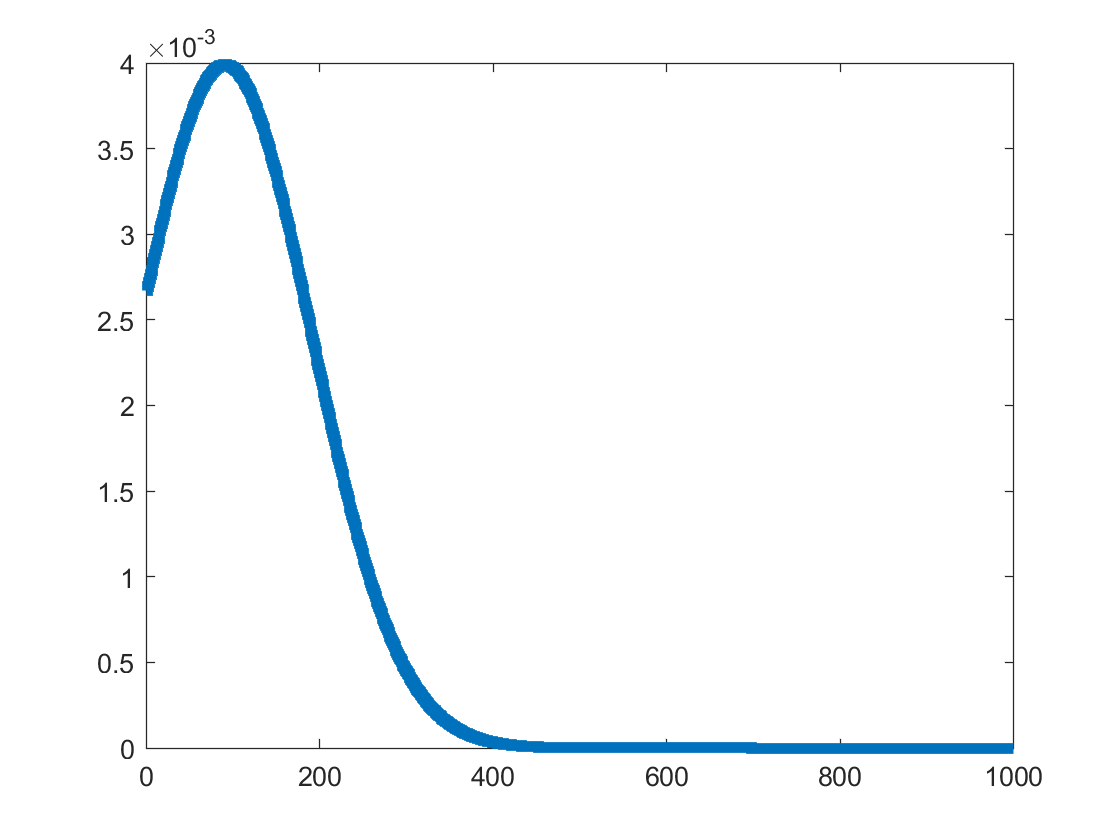

numPixels = 1:1000;
avBright = 90.600;
brightValue = makedist("Normal","mu", avBright,"sigma", 100);
brightDist = pdf(brightValue,numPixels);
stairs(numPixels,brightDist, "Linewidth", 4);

probabilityBright = cdf(brightValue,500.65,"upper")

probabilityBright = 2.0613e-05

sigmaBright = -norminv(probabilityBright)

sigmaBright = 4.1005

Since the sigma value is only 4.1 sigma < 5 sigma needed to claim a discovery, I can't claim that the event was something out of ordinary probability of that event. 

    3.B

What is the probability that the background produces data that is equally or more signal-like?

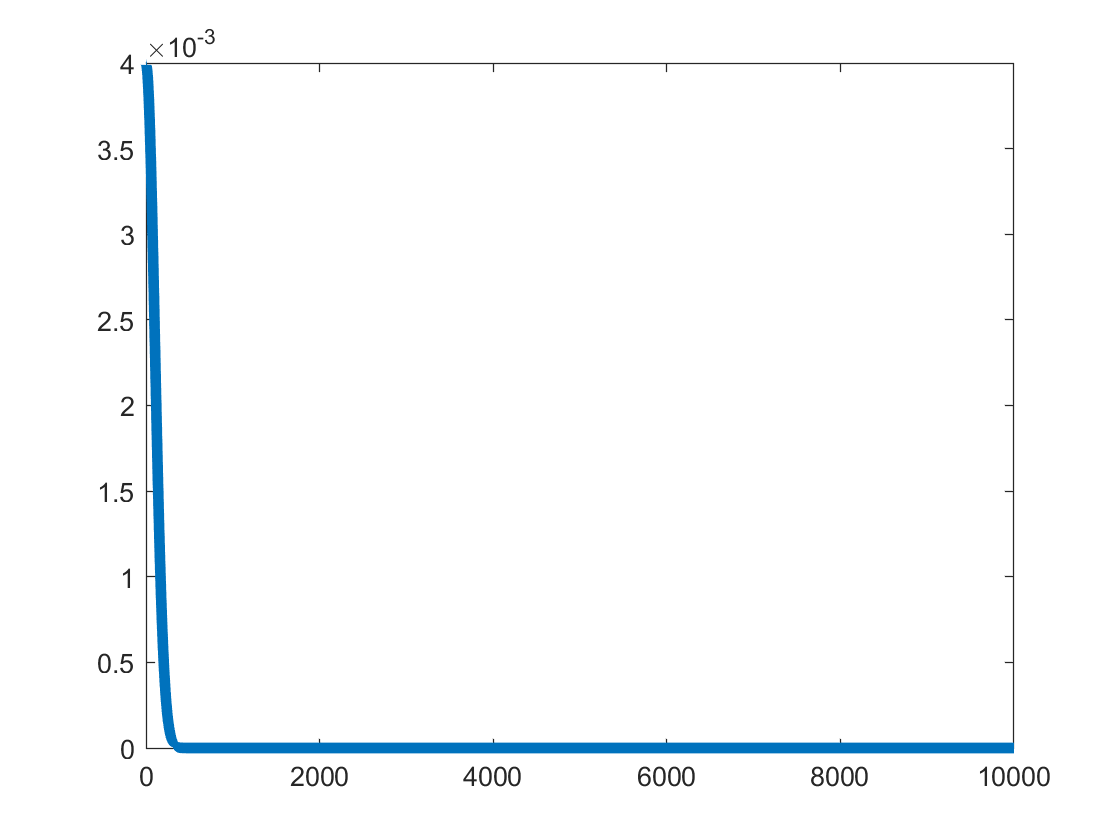

numPixels2 = 1:10000;
background = makedist("Normal", "mu",0,"sigma",100);
pdfBackground = pdf(background,numPixels2);
stairs(numPixels2,pdfBackground,"Linewidth",4);

probabilityBrightBackground = cdf(background,500.65,"upper")

probabilityBrightBackground = 2.7714e-07

    3.C

sigmaBackground = -norminv(probabilityBrightBackground)

sigmaBackground = 5.0065

It's very unlikely that the background produced this signal.

Problem 4

    4.A

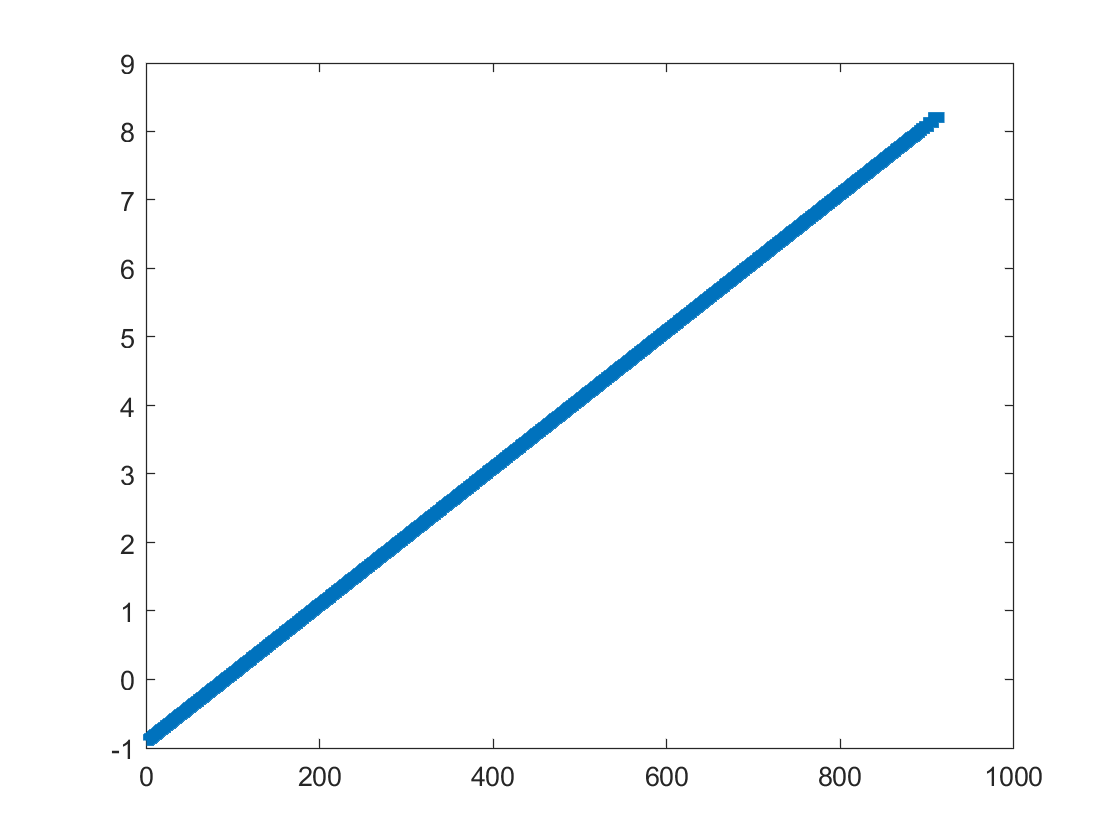

probabilitiesBright = cdf(brightValue,numPixels);
sigmavalues = norminv(probabilitiesBright);
stairs(numPixels,sigmavalues,"Linewidth",4);

the value needed for sigma = 5 is 600

    4.B

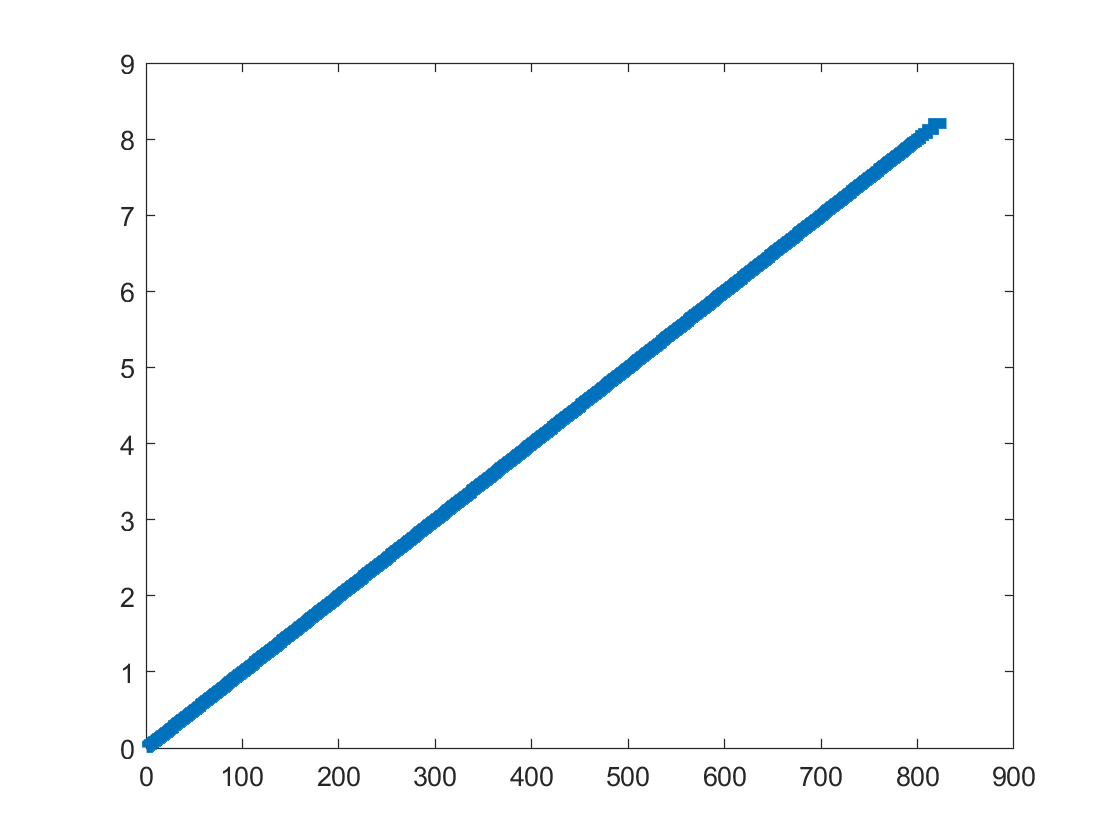

probabilitiesBackground = cdf(background,numPixels2);
sigmavalues = norminv(probabilitiesBackground);
stairs(numPixels2,sigmavalues,"Linewidth",4);

the value needed for sigma = 5 is 500